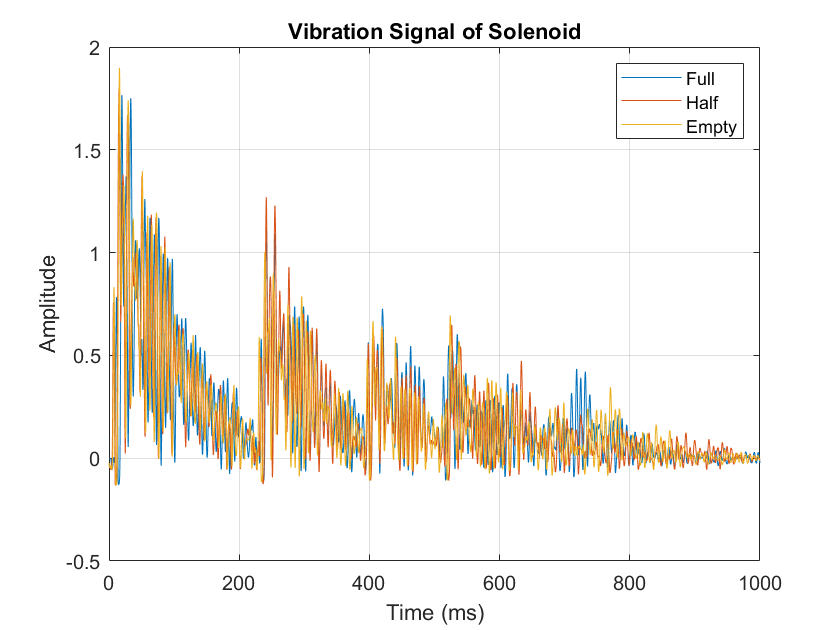


timeLimits = [0 0.0421]; % seconds

%%
SOLENOID_FULL_ROI = SOLENOID_FULL(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(SOLENOID_FULL_ROI)-1))+1;
SOLENOID_FULL_ROI = SOLENOID_FULL_ROI(minIdx:maxIdx);
t = linspace(0,1000, 4211);

%%
SOLENOID_HALF_ROI = SOLENOID_HALF(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(SOLENOID_HALF_ROI)-1))+1;
SOLENOID_HALF_ROI = SOLENOID_HALF_ROI(minIdx:maxIdx);

%%
SOLENOID_EMPTY_ROI = SOLENOID_EMPTY(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(SOLENOID_EMPTY_ROI)-1))+1;
SOLENOID_EMPTY_ROI = SOLENOID_EMPTY_ROI(minIdx:maxIdx);

plot(t,SOLENOID_FULL_ROI, t,SOLENOID_EMPTY_ROI, t,SOLENOID_HALF_ROI)

grid on
legend('Full', 'Half', 'Empty')
title('Vibration Signal of Solenoid')
ylabel('Amplitude')
xlabel('Time (ms)')